## Gradient Descent: OLS

Consider the convex problem


$$\min_{x\in \mathbb{R}^n}f(x)= \frac{1}{2}\|Ax-b\|_2^2$$


where $A$ is a matrix $m\times n$ and $b$ is vector in $\mathbb{R}^{m}$.

m=100;
n=1000;
A=randn(m,n);
xF=randn(n,1);
b=A*xF; %by doing that we guarante that f^*=0


alpha=1;
tol=1e-2

tol = 0.0100

it=1;

maxIt= 1000;
diff = NaN(maxIt,1);
time = NaN(maxIt,1);

xOld=zeros(n,1);
gap=OLS(A,xOld,b);

diff(1)=gap

diff =   155.7407
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


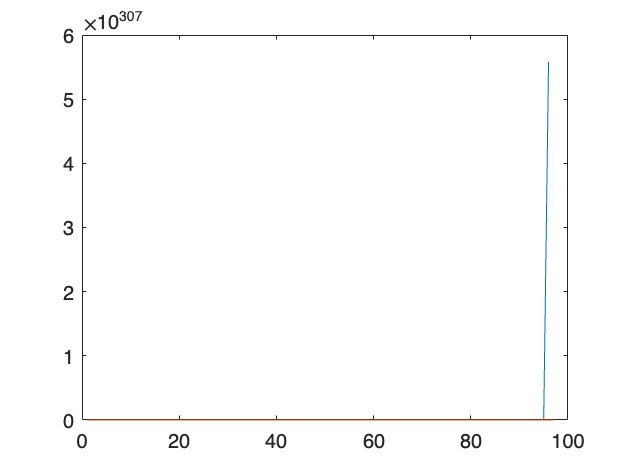

time(1)=0;
tic;
while gap>tol
    
    it=it+1;
    gradf=transpose(A)*(A*xOld-b);
    xNew=xOld-alpha*gradf;
    gap=OLS(A,xNew,b);
    xOld=xNew;

    diff(it)=gap;
    time(it)=time(it-1)+toc;
    tic;
    
end

plot([1:it],diff(1:it,1),[1:it],time(1:it,1));

function value = OLS(A,x,b)

    value = .5*norm(A*x-b,2);

end